# Play with how the spatial scales of waves impacts S2 and FSLE

clear all
close all

% load some model data 
d = 10; 

distance = [10,15]*1e3;

i = 1; 
[mod_traj(i).X, mod_traj(i).Y, mod_traj(i).U, ...
    mod_traj(i).V, mod_traj(i).T, depth(i)] = loadpairs(d(i));

depth = -1.4749e+03

    
% get the velocity from forward differencing (will be important for structure functions)
Unew = nan*mod_traj(i).X;
Vnew = nan*mod_traj(i).X;
dt = 1*24*3600; 
cor = 110*1e3; 

Unew(1:end-1,:) = diff(mod_traj(i).X)*cor.*cosd(mod_traj(i).Y(1:end-1,:))/dt; 
Vnew(1:end-1,:) = diff(mod_traj(i).Y)*cor/dt; 

mod_traj(i).U = Unew; 
mod_traj(i).V = Vnew; 

mod_traj(i).U(mod_traj(i).U==-999) = NaN;
mod_traj(i).V(mod_traj(i).V==-999) = NaN;
mod_traj(i).Y(mod_traj(i).X>360-70) = NaN;
mod_traj(i).U(mod_traj(i).X>360-70) = NaN;
mod_traj(i).V(mod_traj(i).X>360-70) = NaN;
mod_traj(i).X(mod_traj(i).X>360-70) = NaN;

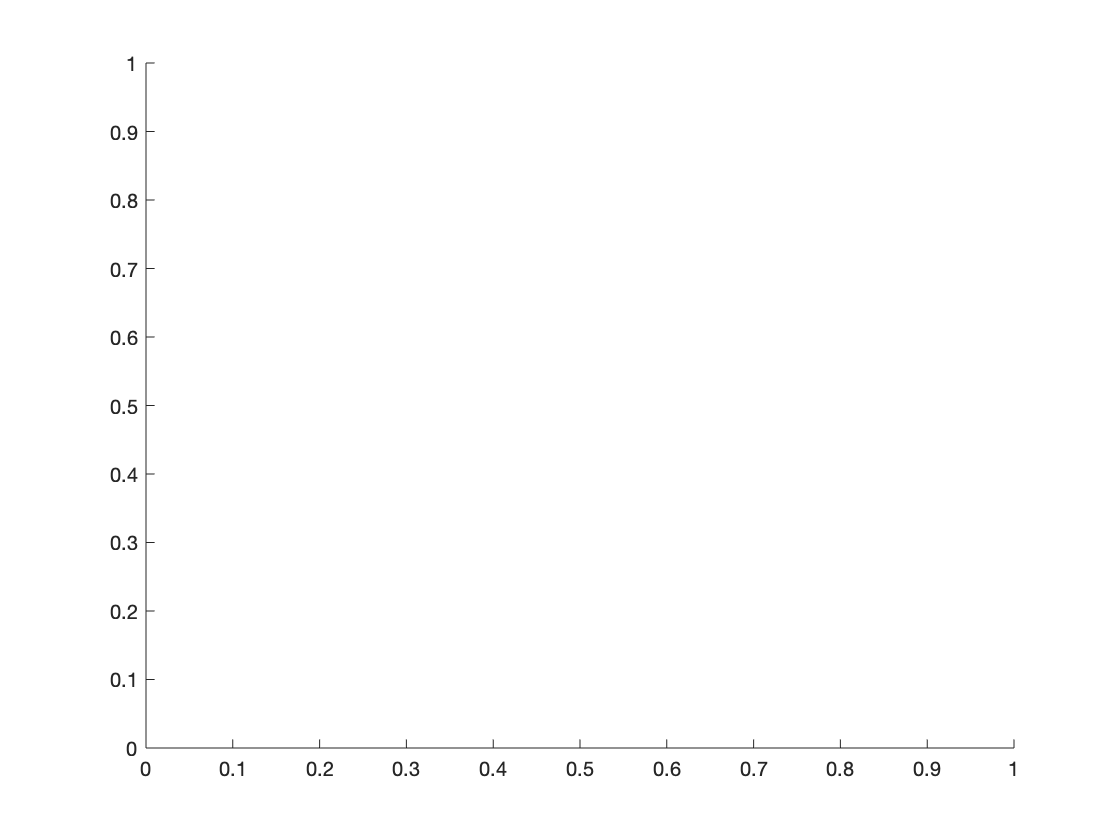

f = 2*2*pi/(1)*sind(-55); % in units of per day

mod_sep_orig = model_sep_calcs_w_NIWs(mod_traj, distance, f, 0,0,0,0);

clear mod_sep_space
L = [50e3, 75e3, 100e3] ;
B= [2.5, 3, 3.5];
slope = [0.4, 0.5, 0.6];
%slope = [3,6,9];

for i = 1:length(L)
    for j = 1:length(B)
        for k = 1:length(slope)
            mod_sep_space(i,j,k) = model_sep_calcs_w_NIWs(mod_traj, distance, f, 1.5/110, (B(j)/110)/(L(i)^(slope(k))), slope(k), 2, L(i));
        end
    end
end


%% first define the distance axis 
gamma = 1.4;
dist_bin(1) = 1000; % in m
dist_bin = gamma.^(0:100)*dist_bin(1);
id = find(dist_bin>800*10^3,1);
dist_bin = dist_bin(1:id);
dist_bin(2:end+1) = dist_bin(1:end);
dist_bin(1) = 0;
dist_axis = 0.5*(dist_bin(1:end-1) + dist_bin(2:end));

flag_1time = 1;

for i = 1:length(L)
    for j = 1:length(B)
        for k = 1:length(slope)
            for n =1:length(mod_sep_orig.sep)
    
                    mod_sep_space(i,j,k).dr_space(:,n) = abs(mod_sep_orig.sep(n).dist - mod_sep_space(i,j,k).sep(n).dist);
                        
                    mod_sep_space(i,j,k).r(:,n) = mod_sep_orig.sep(n).dist;
            end
        end
    end
end



for i = 1:length(L)
    for j = 1:length(B)
        for k = 1:length(slope)
            for n = 1:length(dist_axis)
                
 
                id = find(mod_sep_space(i,j,k).r>=dist_bin(n) & mod_sep_space(i,j,k).r<dist_bin(n+1));

                mod_sep_space(i,j,k).drmean_space(n) = nanmean(mod_sep_space(i,j,k).dr_space(id));
    
            end
        end
    end
end

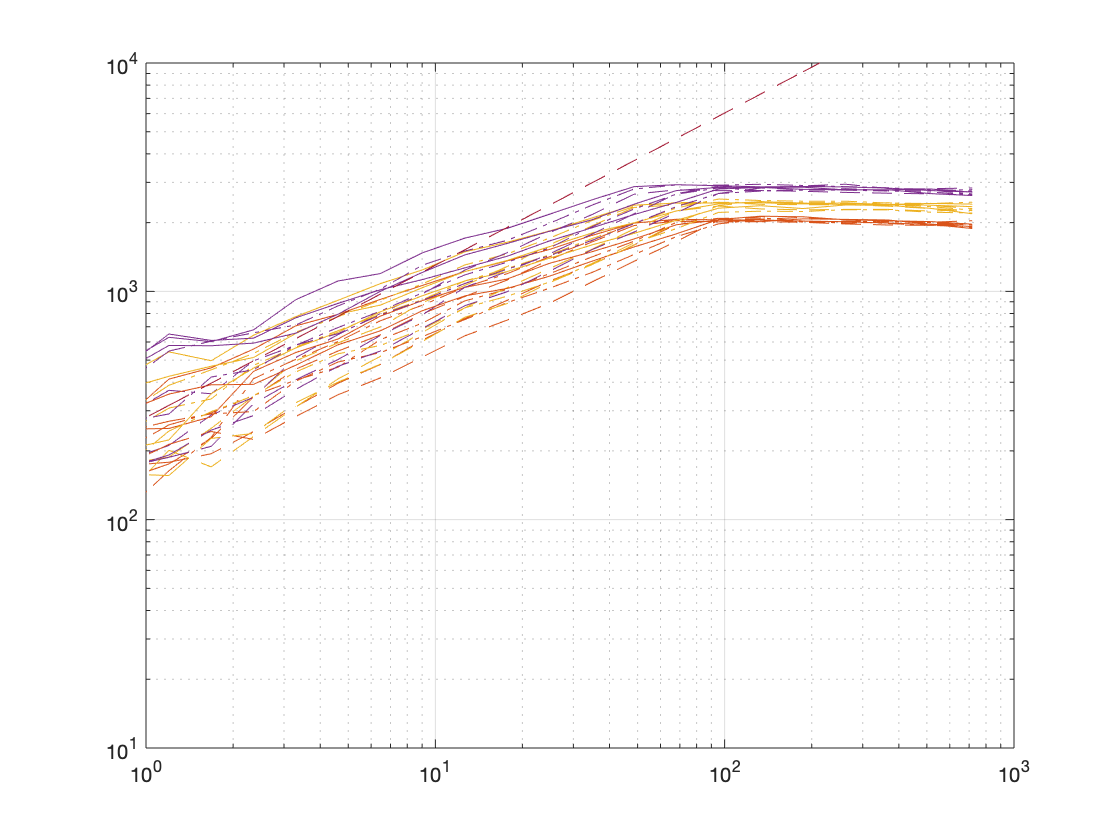

% Plot of spatial dependence of relative magniture
colors = get(gca,'Colororder');

color_list = {colors(2,:); colors(3,:); colors(4,:)}; 
line_list = {'-';'-.';'--'};

figure

for i = 1:length(L)
    for j = 1:length(B)
        for k = 1:length(slope)
            loglog(dist_axis/1e3, mod_sep_space(i,j,k).drmean_space , ...
                'color', color_list{j}, "LineStyle",line_list{k})
            hold all
        end
    end
end
loglog(dist_axis/1e3, 0.5*1e3*(6*((1/35e3*dist_axis).^(2/3))),'--')

axis([1 1000 10 1e4])
grid

## FSLE Orig

fsle_mod_orig = fsle_model(mod_sep_orig.sep, dist_bin, 1, flag_1time); 

for i = 1%[1,3]%1:length(L)
    for j = [1,3]%1:length(B)
        for k = [1,3] %1:length(slope)
            mod_sep_space(i,j,k).fsle_mod_space = fsle_model(mod_sep_space(i,j,k).sep, dist_bin, 1, flag_1time); 
        end
    end
end

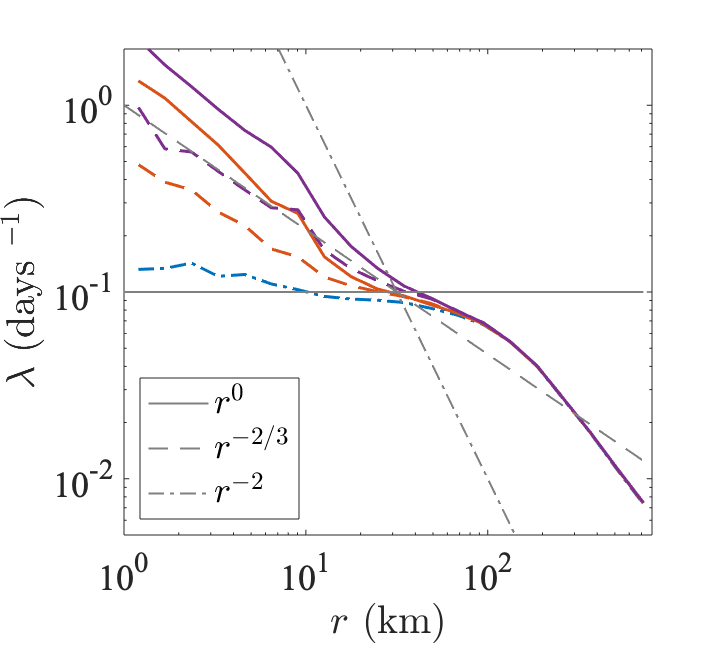

figure('unit','inches','pos',[0. 0. 5, 4.5], 'renderer','painters') 

loglog(dist_axis/1e3, fsle_mod_orig, '-.', 'linewidth',1.5);
hold all

for i = 1%[1,3]%1:length(L)
    for j = [1,3]%1:length(B)
        for k = [1,3] %1:length(slope)
            loglog(dist_axis/1e3, mod_sep_space(i,j,k).fsle_mod_space, ...
                "LineStyle",line_list{k},'color', color_list{j}, 'linewidth',1.5)
        end
    end
end
r0 = loglog(dist_axis/1e3, dist_axis./dist_axis*0.1, '-','color', [0.5 0.5 0.5], 'linewidth',1);  
r23 = loglog(dist_axis/1e3, 100*dist_axis.^(-2/3), '--', 'color', [0.5, 0.5, 0.5], 'linewidth',1); 
r2 = loglog(dist_axis/1e3, 1e8*dist_axis.^(-2), '-.', 'color', [0.5 0.5 0.5], 'linewidth',1); 

A = legend([ r0, r23, r2], ...
    {'$r^{0}$', '$r^{-2/3}$', '$r^{-2}$'} ...
    , 'Interpreter','Latex', 'location','southwest', 'fontsize',18);

set(gca, 'fontsize', 18, 'fontname','times') 

axis([1 800 50*1e-4 2]) 


xlabel('$r$ (km)', 'Interpreter', 'Latex') 
ylabel('$\lambda$ (days $^{-1}$)', 'Interpreter','Latex')

print('NIWs_FSLE.eps', '-depsc', '-r400')

## S2

S2ll_orig = S2ll_model(mod_sep_orig.sep, dist_bin);

for i = 1%[1,3]%1:length(L)
    for j = [1,3]%1:length(B)
        for k = [1,3]%1:length(slope)
            mod_sep_space(i,j,k).S2ll_space = S2ll_model(mod_sep_space(i,j,k).sep, dist_bin);
        end
    end
end

%S2ll_space2 = S2ll_model(mod_sep_space2.sep, dist_bin);

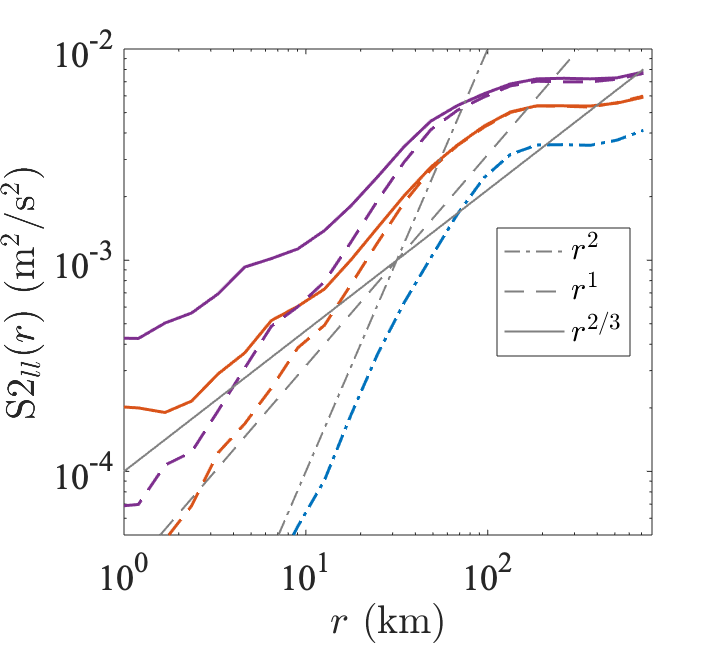

figure('unit','inches','pos',[0. 0. 5, 4.5], 'renderer','painters')
        
loglog(dist_axis/1e3, S2ll_orig,'-.', 'linewidth',1.5,'color',colors(1,:));
hold all


for i = 1%[1,3]%1:length(L)
    for j = [1,3]%1:length(B)
        for k = [1,3]%1:length(slope)
            loglog(dist_axis/1e3, mod_sep_space(i,j,k).S2ll_space, ...
                 "LineStyle",line_list{k}, 'color', color_list{j},'linewidth',1.5)
        end
    end
end


r23 = loglog(dist_axis/1e3, 1e-6*dist_axis.^(2/3), '-','color', [0.5 0.5 0.5], 'linewidth',1.);
r1 =loglog(dist_axis/1e3, 10^(-7.5)*dist_axis.^(1), '--','color', [0.5 0.5 0.5], 'linewidth',1.);
r2 =loglog(dist_axis/1e3, 1e-12*dist_axis.^(2), '-.','color', [0.5 0.5 0.5], 'linewidth',1.);

A = legend([r2, r1, r23], ...
    {  '$r^{2}$', '$r^{1}$', '$r^{2/3}$'} ...
    , 'Interpreter','Latex', 'location','best');

set(gca, 'fontsize', 18, 'fontname', 'times') 

axis([1 800 5e-5 1e-2])
xlabel('$r$ (km)', 'Interpreter', 'Latex') 
ylabel('S2$_{ll} (r)$ (m$^{2}$/s$^{2}$)', 'Interpreter','Latex')

print('NIWs_S2.eps', '-depsc', '-r400')

## Freq Spectrum

[mod_sep_orig.F, mod_sep_orig.SPP, mod_sep_orig.SNN, mod_sep_orig.SPN] = spec_pairs(mod_sep_orig,1);

SLEPTAP calculating tapers of length 120.


for i = 1:length(L)
    for j = 1:length(B)
        for k = 1:length(slope)
            [mod_sep_space(i,j,k).F, mod_sep_space(i,j,k).SPP, mod_sep_space(i,j,k).SNN, ...
                mod_sep_space(i,j,k).SPN] = spec_pairs(mod_sep_space(i,j,k),1);
        end
    end
end

SLEPTAP calculating tapers of length 120.
SLEPTAP calculating tapers of length 120.
SLEPTAP calculating tapers of length 120.
SLEPTAP calculating tapers of length 120.
SLEPTAP calculating tapers of length 120.
SLEPTAP calculating tapers of length 120.
SLEPTAP calculating tapers of length 120.
SLEPTAP calculating tapers of length 120.
SLEPTAP calculating tapers of length 120.
SLEPTAP calculating tapers of length 120.
SLEPTAP calculating tapers of length 120.
SLEPTAP calculating tapers of length 120.
SLEPTAP calculating tapers of length 120.
SLEPTAP calculating tapers of length 120.
SLEPTAP calculating tapers of length 120.
SLEPTAP calculating tapers of length 120.
SLEPTAP calculating tapers of length 120.
SLEPTAP calculating tapers of length 120.
SLEPTAP calculating tapers of length 120.
SLEPTAP calculating tapers of length 120.
SLEPTAP calculating tapers of length 120.
SLEPTAP calculating tapers of length 120.
SLEPTAP calculating tapers of length 120.
SLEPTAP calculating tapers of leng

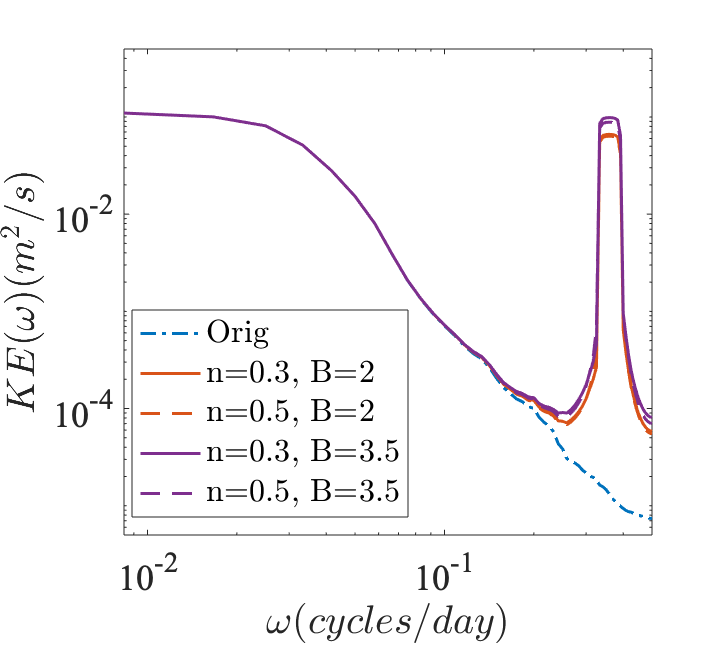

figure('unit','inches','pos',[0. 0. 5, 4.5], 'renderer','painters')
loglog(mod_sep_orig.F, nanmean(mod_sep_orig.SPP + mod_sep_orig.SNN,2),'-.', 'linewidth',1.5,'color',colors(1,:));
hold all 
for i = 1%[1,3]%1:length(L)
    for j = [1,3]%1:length(B)
        for k = [1,3]%1:length(slope)
            loglog(mod_sep_space(i,j,k).F, nanmean(mod_sep_space(i,j,k).SPP +  mod_sep_space(i,j,k).SNN,2), ...
                 "LineStyle",line_list{k}, 'color', color_list{j},'linewidth',1.5)
        end
    end
end


set(gca, 'fontsize', 18, 'fontname', 'times') 
xlabel('$\omega (cycles/day)$','Interpreter',"latex")
ylabel('$KE (\omega) (m^2/s)$','Interpreter',"latex")

xlim([1/120, 1/2])
ylim([5e-6, 0.5])

legend('Orig', 'n=0.3, B=2', 'n=0.5, B=2', 'n=0.3, B=3.5', 'n=0.5, B=3.5',...
    'location', 'best','interpreter','Latex')

print('NIWs_freq.eps', '-depsc', '-r400')

## Relative Dispersion

ndays = 100;
disp_orig = rel_disp(mod_sep_orig.sep, ndays);
mod_sep_orig.disp = disp_orig.avdisp/1e6;

for i = 1:length(L)
    for j = 1:length(B)
        for k = 1:length(slope)
            disp_orig = rel_disp(mod_sep_space(i,j,k).sep, ndays);
            mod_sep_space(i,j,k).disp = disp_orig.avdisp/1e6; 
        end
    end
end

T=[0:99];

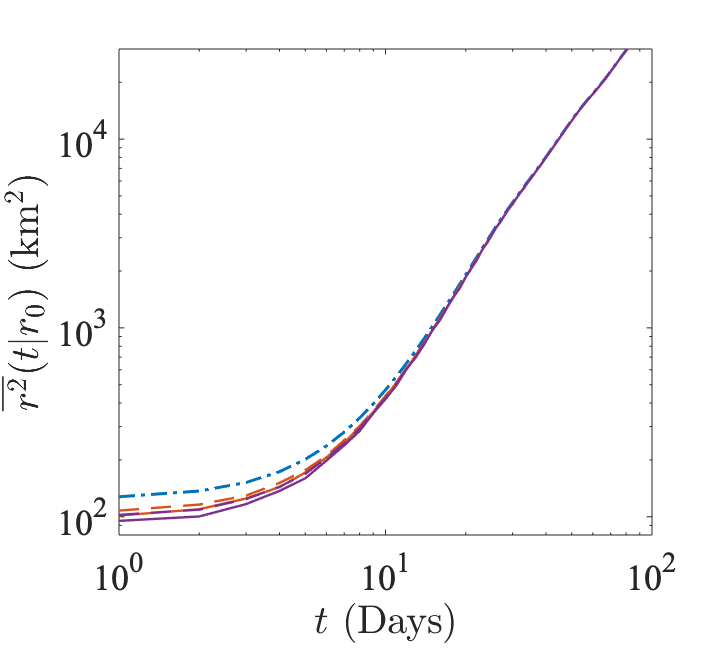

clear h g
figure('unit','inches','pos',[0. 0., 5, 4.5], 'renderer','painters')
j=1;

loglog(T, mod_sep_orig.disp, '-.', 'color', colors(1,:), 'linewidth', 1.5)
hold all
for i = 1%[1,3]%1:length(L)
    for j = [1,3]%1:length(B)
        for k = [1,3]%1:length(slope)
            loglog(T, mod_sep_space(i,j,k).disp, ...
                 "LineStyle", line_list{k}, 'color', color_list{j},'linewidth',1.2)
        end
    end
end
%loglog(T, disptime, '-', 'color', colors(2,:), 'linewidth', 1.5)
%loglog(T, dispspace, '-', 'color', colors(3,:), 'linewidth', 1.5)

axis([1 100 0.8*10^2 3*10^4])

set(gca,'FontSize', 18,'fontname','times')
xlabel('$t$ (Days)', 'Interpreter','Latex') 
ylabel('$\overline{r^2}(t| r_0)$ (km$^2$)', 'Interpreter','Latex')

print('NIWs_disp.eps', '-depsc', '-r400')

## Relative Diffusivity

mod_sep_orig_4_rd = model_sep_calcs_w_NIWs(mod_traj, [0,50]*1e3,0,0,0,0,0);
mod_sep_orig.rd_1 = rel_diff_inst_model(mod_sep_orig_4_rd.sep, dist_bin,1); 
mod_sep_orig.rd_6 = rel_diff_inst_model(mod_sep_orig_4_rd.sep, dist_bin,6); 

for i = 1%[1,3]%1:length(L)
    for j = [1,3]%1:length(B)
        for k = [1,3]%1:length(slope)
               mod_sep_space_4_rd = model_sep_calcs_w_NIWs(mod_traj, [0,50]*1e3, f, 1.5/110, (B(j)/110)/(L(i)^(slope(k))), slope(k), 2, L(i));
               mod_sep_space(i,j,k).rd_1 = rel_diff_inst_model(mod_sep_space_4_rd.sep, dist_bin,1); 
               mod_sep_space(i,j,k).rd_6 = rel_diff_inst_model(mod_sep_space_4_rd.sep, dist_bin,6);          
        end
    end
end

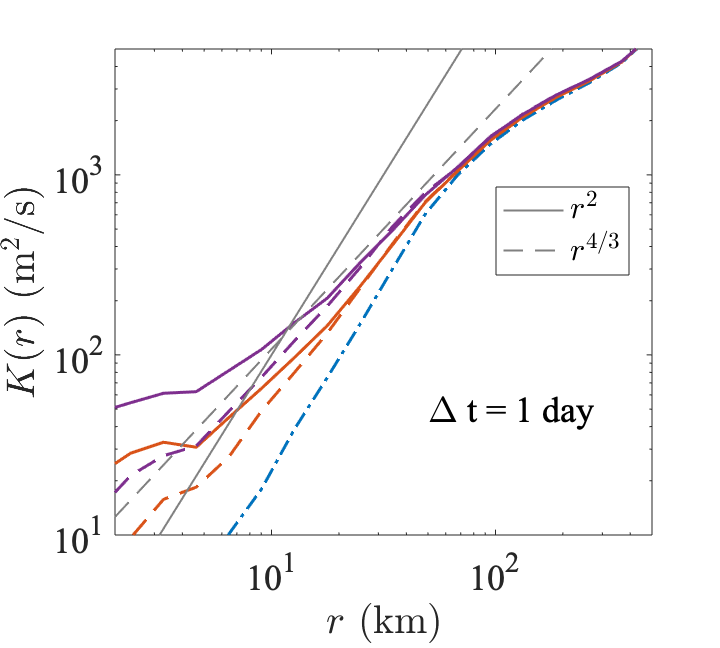

clear h g 
figure('unit','inches','pos',[0. 0., 5, 4.5], 'renderer','painters')

loglog(dist_axis/1e3, mod_sep_orig.rd_1.rdmean,'-.', 'linewidth',1.5,'color', colors(1,:));
hold all 
for i = 1%[1,3]%1:length(L)
    for j = [1,3]%1:length(B)
        for k = [1,3]%1:length(slope)
            loglog(dist_axis/1e3, mod_sep_space(i,j,k).rd_1.rdmean, "LineStyle", line_list{k}, 'linewidth',1.5, 'color', color_list{j});
        end
    end
end



r2 = loglog(dist_axis/1e3, 1e-6*dist_axis.^2, '-','color', [0.5 0.5 0.5], 'linewidth',1);
r43 = loglog(dist_axis/1e3, 5e-4*dist_axis.^(4/3), '--','color', [0.5 0.5 0.5], 'linewidth',1);


A = legend([r2, r43], ...
    {'$r^{2}$', '$r^{4/3}$'}, 'location', 'best' ...
    , 'Interpreter','Latex');
%legend boxoff
%set(A, 'location','best') 

axis([2 500 10 5e3])
set(gca, 'fontsize', 18, 'fontname','times') 

text(50,50,'\Delta t = 1 day','fontsize', 18, 'fontname','times')


xlabel('$r$ (km)', 'Interpreter', 'Latex') 
ylabel('$K (r)$ (m$^{2}/$s)', 'Interpreter','Latex')
print('NIWs_diff1.eps', '-depsc', '-r400')

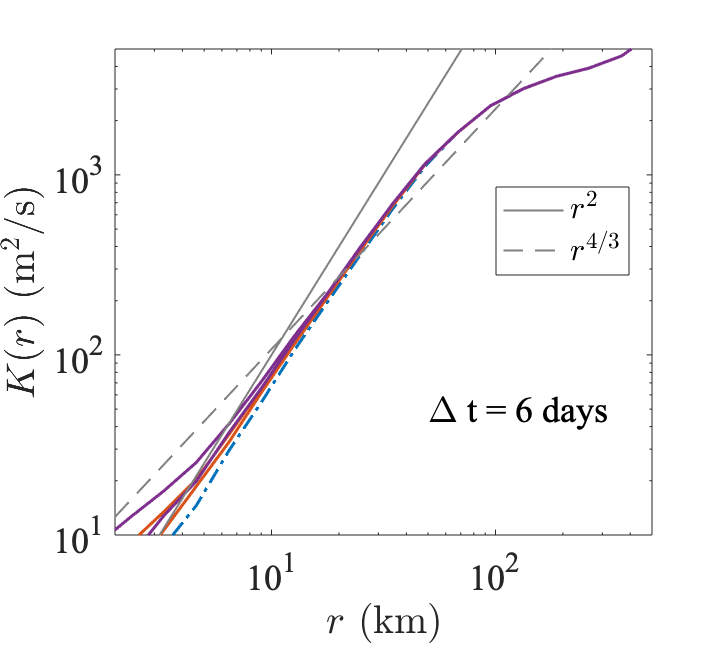

clear h g 
figure('unit','inches','pos',[0. 0., 5, 4.5], 'renderer','painters')

loglog(dist_axis/1e3, mod_sep_orig.rd_6.rdmean,'-.', 'linewidth',1.5,'color', colors(1,:));

hold all 
for i = 1%[1,3]%1:length(L)
    for j = [1,3]%1:length(B)
        for k = [1,3]%1:length(slope)
            loglog(dist_axis/1e3, mod_sep_space(i,j,k).rd_6.rdmean,'-', 'linewidth',1.5, 'color', color_list{j});
        end
    end
end



r2 = loglog(dist_axis/1e3, 1e-6*dist_axis.^2, '-','color', [0.5 0.5 0.5], 'linewidth',1);
r43 = loglog(dist_axis/1e3, 5e-4*dist_axis.^(4/3), '--','color', [0.5 0.5 0.5], 'linewidth',1);


A = legend([r2, r43], ...
    {'$r^{2}$', '$r^{4/3}$'}, 'location', 'best' ...
    , 'Interpreter','Latex');
%legend boxoff
%set(A, 'location','best') 

axis([2 500 10 5e3])
set(gca, 'fontsize', 18, 'fontname','times') 


text(50,50,'\Delta t = 6 days','fontsize', 18, 'fontname','times')

xlabel('$r$ (km)', 'Interpreter', 'Latex') 
ylabel('$K (r)$ (m$^{2}/$s)', 'Interpreter','Latex')
print('NIWs_diff6.eps', '-depsc', '-r400')

function [F, SPP, SNN, SPN] = spec_pairs(sep, dT)
len = 120/dT;
psi = sleptap(len);
npairs  = length(sep.sep);
CV = zeros(len, 2*npairs);

n=1;
for i = 1:npairs
    CV(:,n) = sep.sep(i).U1(1:len) + sqrt(-1)*sep.sep(i).V1(1:len);
    n=n+1;
    CV(:,n) = sep.sep(i).U2(1:len) + sqrt(-1)*sep.sep(i).V2(1:len);
    n=n+1;
end

[F, SPP, SNN, SPN] = mspec(dT, CV, psi,'cyclic');

end